# Multiple linear regression

%load files and set workspace
% excludeSubjects;
load('relevant_ss.mat')
load('D:\Documents\software\MetaLabCore\project_params.mat');
load(fullfile(project_params.raw_dir,'subject_details.mat'));
p=project_params;
addpath(p.spm_dir);
cwd = pwd;

%add nice things to path
addpath('D:\Documents\software\cbrewer') %for color
addpath('D:\Documents\software\sigstar') %for significance
[cb] = cbrewer('qual','Set1',10,'pchip');
cb_dis = cbrewer('div','PRGn',18,'pchip');
cb_det = cbrewer('div','RdBu',18,'pchip');
cb_dis = cb_dis([1:6,13:18],:);
cb_det = cb_det([1:6,13:18],:);
mappingcb = cbrewer('div','BrBG',3);
addpath('D:\Documents\software\raincloud_plots') %for rainclouds

% good_ss = find(sum((toExclude+toExcludeFromConfAnalyses)>0,2)<5)';


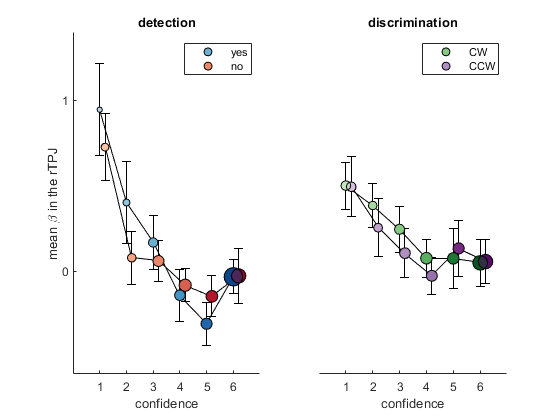

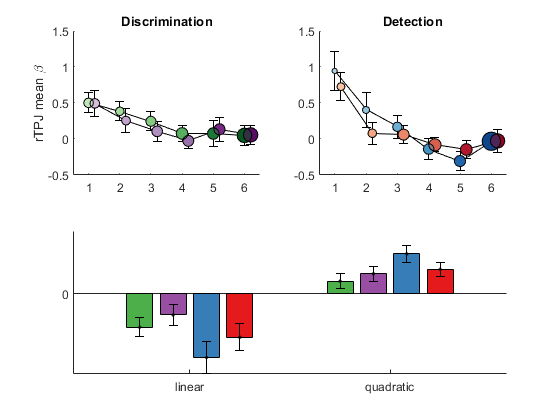

[ax1_rTPJ,ax2_rTPJ, rTPJ_coefs]=plotQuadFit(project_params,good_ss,'rTPJ','rTPJ');

compareCoefs(rTPJ_coefs)

quad_global_p = 1.3636e-05

quad_global_stats = struct with fields:
    tstat: 5.0774
       df: 34
       sd: 0.0884


linear_global_p = 2.9420e-06

liner_global_stats = struct with fields:
    tstat: -5.5896
       df: 34
       sd: 0.1364


quad_task_p = 0.0692

quad_task_stats = struct with fields:
    tstat: 1.8767
       df: 34
       sd: 0.1165


linear_task_p = 0.0037

linear_task_stats = struct with fields:
    tstat: -3.1130
       df: 34
       sd: 0.1944


quad_resp_p = 0.1496

quad_resp_stats = struct with fields:
    tstat: 1.4754
       df: 33
       sd: 0.1807


linear_resp_p = 0.3795

linear_resp_stats = struct with fields:
    tstat: -0.8909
       df: 33
       sd: 0.4159


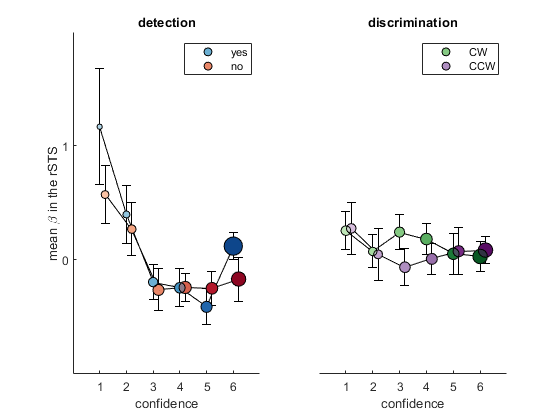

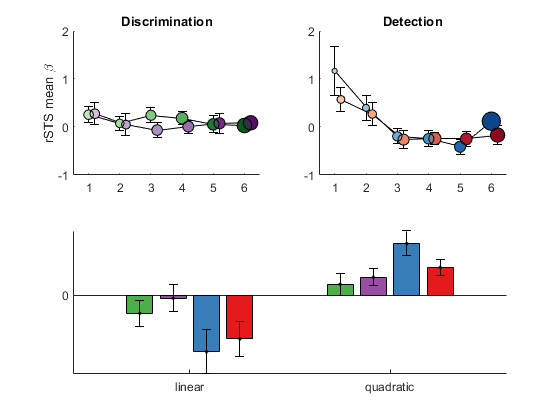

[ax1_rSTS,ax2_rSTS, rSTS_coefs]=plotQuadFit(project_params,good_ss,'rSTS','rSTS');

compareCoefs(rSTS_coefs)

quad_global_p = 2.1840e-04

quad_global_stats = struct with fields:
    tstat: 4.1368
       df: 34
       sd: 0.1233


linear_global_p = 0.0039

liner_global_stats = struct with fields:
    tstat: -3.0964
       df: 34
       sd: 0.1846


quad_task_p = 0.0214

quad_task_stats = struct with fields:
    tstat: 2.4125
       df: 34
       sd: 0.1680


linear_task_p = 0.0080

linear_task_stats = struct with fields:
    tstat: -2.8179
       df: 34
       sd: 0.3065


quad_resp_p = 0.0525

quad_resp_stats = struct with fields:
    tstat: 2.0113
       df: 33
       sd: 0.2193


linear_resp_p = 0.7043

linear_resp_stats = struct with fields:
    tstat: -0.3828
       df: 33
       sd: 0.4510


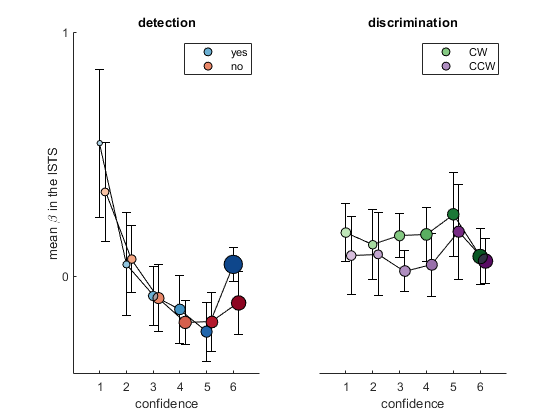

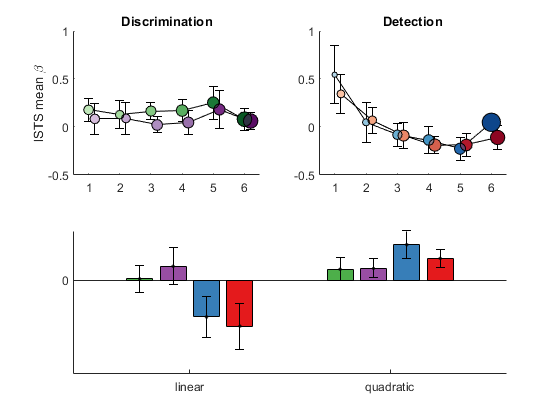

[ax1_lSTS,ax2_lSTS, lSTS_coefs]=plotQuadFit(project_params,good_ss,'lSTS','lSTS');

compareCoefs(lSTS_coefs)

quad_global_p = 0.0131

quad_global_stats = struct with fields:
    tstat: 2.6181
       df: 34
       sd: 0.0961


linear_global_p = 0.0756

liner_global_stats = struct with fields:
    tstat: -1.8327
       df: 34
       sd: 0.1125


quad_task_p = 0.1082

quad_task_stats = struct with fields:
    tstat: 1.6498
       df: 34
       sd: 0.1250


linear_task_p = 0.0019

linear_task_stats = struct with fields:
    tstat: -3.3631
       df: 34
       sd: 0.2004


quad_resp_p = 0.2984

quad_resp_stats = struct with fields:
    tstat: 1.0565
       df: 33
       sd: 0.1530


linear_resp_p = 0.6633

linear_resp_stats = struct with fields:
    tstat: 0.4393
       df: 33
       sd: 0.3776


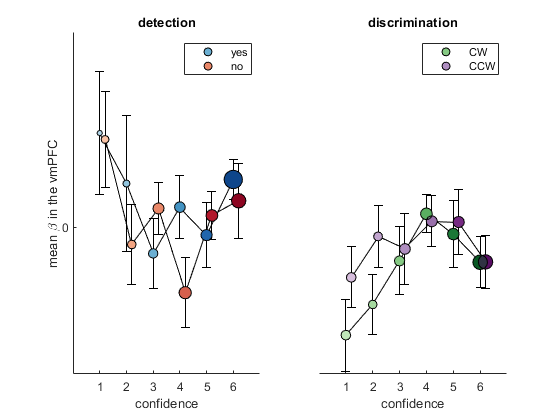

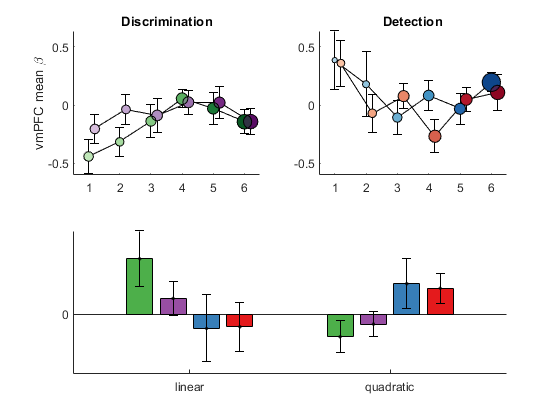

[ax1_vmPFC,ax2_vmPFC, vmPFC_coefs]=plotQuadFit(project_params,good_ss,'vmPFC','vmPFC');

compareCoefs(vmPFC_coefs)

quad_global_p = 0.4850

quad_global_stats = struct with fields:
    tstat: 0.7059
       df: 34
       sd: 0.0811


linear_global_p = 0.4145

liner_global_stats = struct with fields:
    tstat: 0.8262
       df: 34
       sd: 0.1428


quad_task_p = 0.0248

quad_task_stats = struct with fields:
    tstat: 2.3482
       df: 34
       sd: 0.1615


linear_task_p = 0.2669

linear_task_stats = struct with fields:
    tstat: -1.1289
       df: 34
       sd: 0.2278


quad_resp_p = 0.8280

quad_resp_stats = struct with fields:
    tstat: 0.2190
       df: 33
       sd: 0.2366


linear_resp_p = 0.9031

linear_resp_stats = struct with fields:
    tstat: 0.1227
       df: 33
       sd: 0.3665


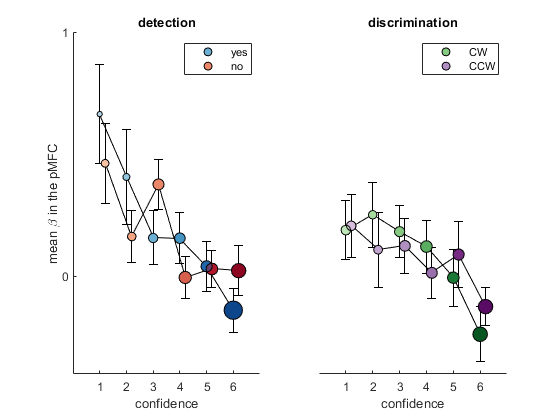

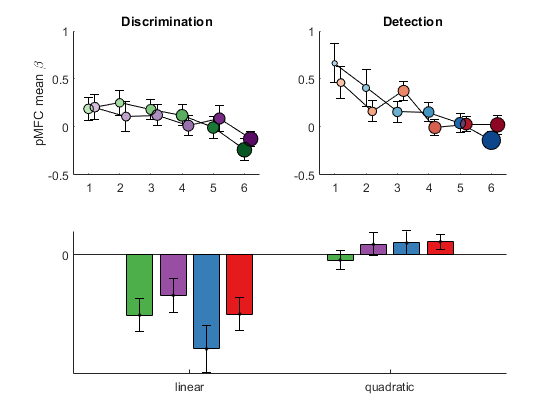

[ax1_pMFC,ax2_pMFC, pMFC_coefs]=plotQuadFit(project_params,good_ss,'pMFC','pMFC');

compareCoefs(pMFC_coefs)

quad_global_p = 0.2021

quad_global_stats = struct with fields:
    tstat: 1.3008
       df: 34
       sd: 0.0540


linear_global_p = 7.8587e-06

liner_global_stats = struct with fields:
    tstat: -5.2616
       df: 34
       sd: 0.1181


quad_task_p = 0.9278

quad_task_stats = struct with fields:
    tstat: 0.0913
       df: 34
       sd: 0.0787


linear_task_p = 0.0339

linear_task_stats = struct with fields:
    tstat: -2.2107
       df: 34
       sd: 0.1512


quad_resp_p = 0.7673

quad_resp_stats = struct with fields:
    tstat: -0.2984
       df: 33
       sd: 0.1226


linear_resp_p = 0.2678

linear_resp_stats = struct with fields:
    tstat: -1.1271
       df: 33
       sd: 0.2684


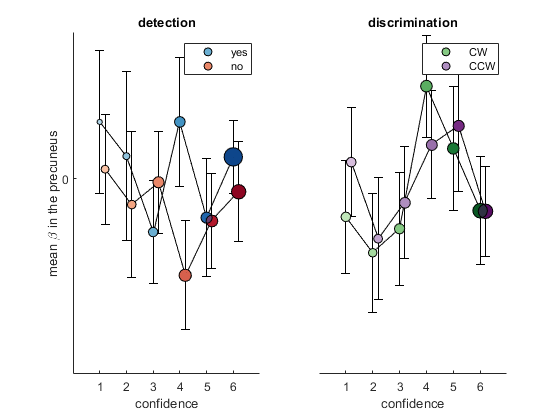

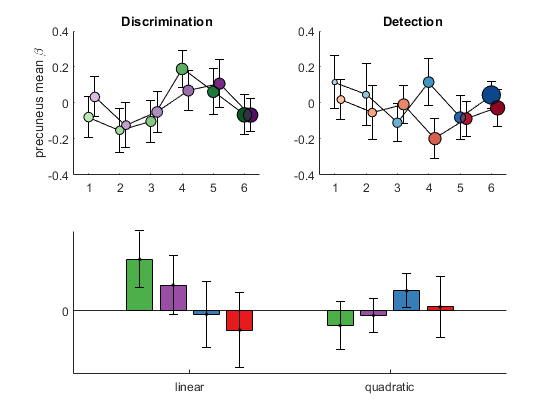


[ax1_precuneus,ax2_precuneus, precuneus_coefs]=plotQuadFit(project_params,good_ss,'precuneus','precuneus');

compareCoefs(precuneus_coefs)

quad_global_p = 0.9179

quad_global_stats = struct with fields:
    tstat: 0.1038
       df: 34
       sd: 0.0634


linear_global_p = 0.4004

liner_global_stats = struct with fields:
    tstat: 0.8515
       df: 34
       sd: 0.0787


quad_task_p = 0.3608

quad_task_stats = struct with fields:
    tstat: 0.9263
       df: 34
       sd: 0.0918


linear_task_p = 0.1655

linear_task_stats = struct with fields:
    tstat: -1.4172
       df: 34
       sd: 0.1183


quad_resp_p = 0.5244

quad_resp_stats = struct with fields:
    tstat: 0.6434
       df: 33
       sd: 0.1414


linear_resp_p = 0.7092

linear_resp_stats = struct with fields:
    tstat: 0.3762
       df: 33
       sd: 0.2299


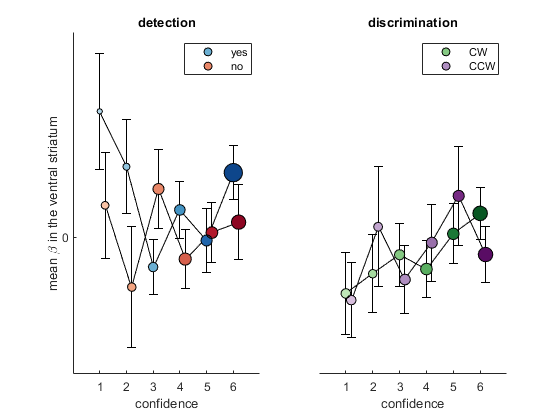

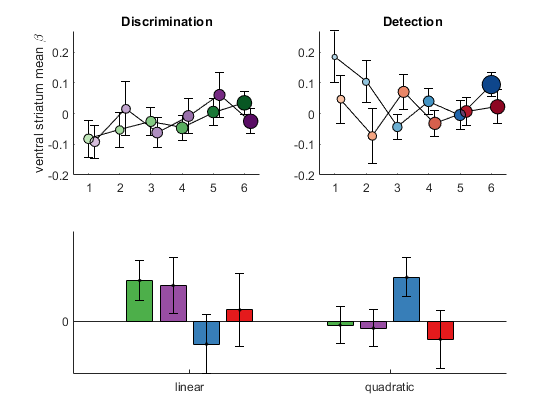

[ax1_VS,ax2_VS, VS_coefs]=plotQuadFit(project_params,good_ss,'ventralStriatum','ventral striatum');

compareCoefs(VS_coefs)

quad_global_p = 0.7051

quad_global_stats = struct with fields:
    tstat: 0.3816
       df: 34
       sd: 0.0244


linear_global_p = 0.3618

liner_global_stats = struct with fields:
    tstat: 0.9243
       df: 34
       sd: 0.0502


quad_task_p = 0.2684

quad_task_stats = struct with fields:
    tstat: 1.1253
       df: 34
       sd: 0.0489


linear_task_p = 0.1908

linear_task_stats = struct with fields:
    tstat: -1.3348
       df: 34
       sd: 0.0750


quad_resp_p = 0.0547

quad_resp_stats = struct with fields:
    tstat: 1.9918
       df: 33
       sd: 0.0856


linear_resp_p = 0.4488

linear_resp_stats = struct with fields:
    tstat: -0.7666
       df: 33
       sd: 0.0950


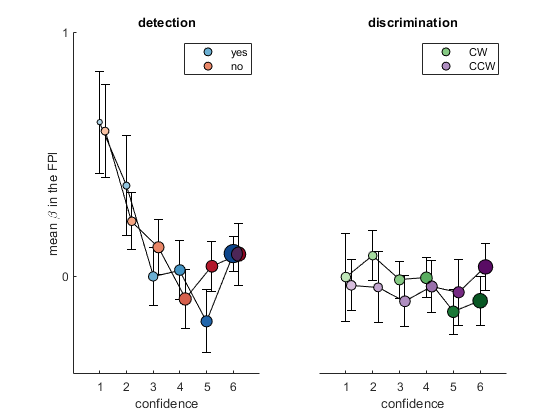

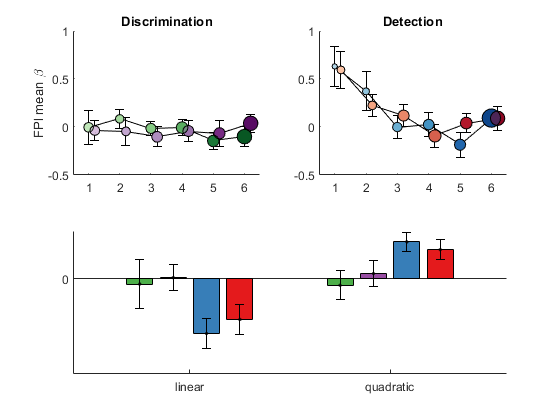

[ax1_FPl,ax2_FPl, FPl_coefs]=plotQuadFit(project_params,good_ss,'FPl','FPl');

compareCoefs(FPl_coefs)

quad_global_p = 0.0293

quad_global_stats = struct with fields:
    tstat: 2.2759
       df: 34
       sd: 0.0861


linear_global_p = 0.0180

liner_global_stats = struct with fields:
    tstat: -2.4852
       df: 34
       sd: 0.1222


quad_task_p = 5.0397e-04

quad_task_stats = struct with fields:
    tstat: 3.8449
       df: 34
       sd: 0.0885


linear_task_p = 3.9769e-04

linear_task_stats = struct with fields:
    tstat: -3.9281
       df: 34
       sd: 0.1502


quad_resp_p = 0.5969

quad_resp_stats = struct with fields:
    tstat: 0.5340
       df: 33
       sd: 0.1603


linear_resp_p = 0.5174

linear_resp_stats = struct with fields:
    tstat: -0.6544
       df: 33
       sd: 0.2203


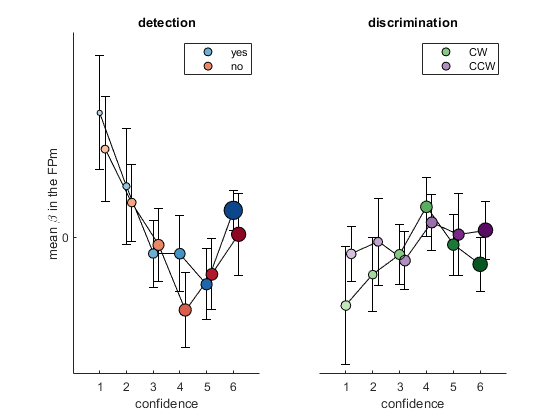

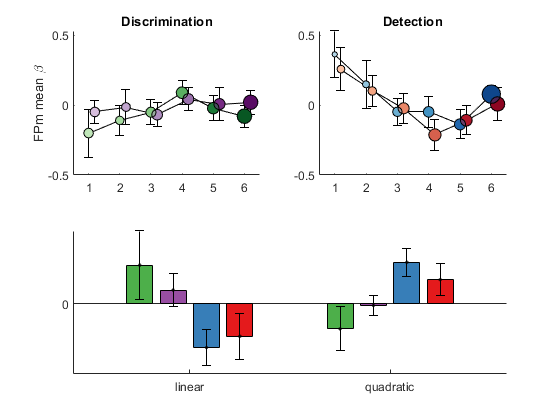

[ax1_FPm,ax2_FPm, FPm_coefs]=plotQuadFit(project_params,good_ss,'FPm','FPm');

compareCoefs(FPm_coefs)

quad_global_p = 0.3072

quad_global_stats = struct with fields:
    tstat: 1.0367
       df: 34
       sd: 0.0797


linear_global_p = 0.6027

liner_global_stats = struct with fields:
    tstat: -0.5254
       df: 34
       sd: 0.0843


quad_task_p = 0.0030

quad_task_stats = struct with fields:
    tstat: 3.1929
       df: 34
       sd: 0.0915


linear_task_p = 0.0049

linear_task_stats = struct with fields:
    tstat: -3.0068
       df: 34
       sd: 0.1426


quad_resp_p = 0.4088

quad_resp_stats = struct with fields:
    tstat: 0.8367
       df: 33
       sd: 0.1788


linear_resp_p = 0.7043

linear_resp_stats = struct with fields:
    tstat: -0.3828
       df: 33
       sd: 0.2002


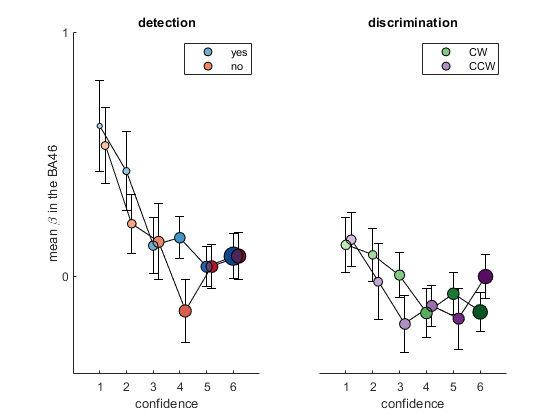

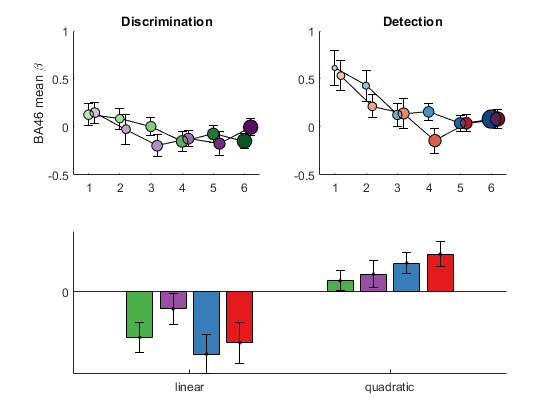

[ax1_BA46,ax2_BA46, BA46_coefs]=plotQuadFit(project_params,good_ss,'BA46','BA46');

compareCoefs(BA46_coefs)

quad_global_p = 1.9287e-04

quad_global_stats = struct with fields:
    tstat: 4.1798
       df: 34
       sd: 0.0549


linear_global_p = 1.5195e-04

liner_global_stats = struct with fields:
    tstat: -4.2618
       df: 34
       sd: 0.0989


quad_task_p = 0.0777

quad_task_stats = struct with fields:
    tstat: 1.8191
       df: 34
       sd: 0.0793


linear_task_p = 0.0199

linear_task_stats = struct with fields:
    tstat: -2.4439
       df: 34
       sd: 0.1507


quad_resp_p = 0.5436

quad_resp_stats = struct with fields:
    tstat: -0.6137
       df: 33
       sd: 0.1652


linear_resp_p = 0.7534

linear_resp_stats = struct with fields:
    tstat: -0.3168
       df: 33
       sd: 0.2476
